# Lab 4

## Section 1 H=Vout/Vin

syms s R1 R2 C
Zc = 1/(s*C)

$$Zc = \frac{1}{C\,s}$$

Zs = simplifyFraction(R2 + Zc)

$$Zs = \frac{C\,R_{2}\,s+1}{C\,s}$$

H = simplifyFraction(Zs/(R1+Zs))

$$H = \frac{C\,R_{2}\,s+1}{C\,R_{1}\,s+C\,R_{2}\,s+1}$$

R1 = 4; R2 = 2; C = 3;
H = subs(H)

$$H = \frac{6\,s+1}{18\,s+1}$$

## Section 2 Impulse and Step

[sysNum, sysDen] = numden(H)

$$sysNum = 6\,s+1$$

$$sysDen = 18\,s+1$$

num = sym2poly(sysNum)

num =      6     1


den = sym2poly(sysDen)

den =     18     1



HTF = tf(num,den)

HTF =
 
  6 s + 1
  --------
  18 s + 1
 
Continuous-time transfer function.
Model Properties


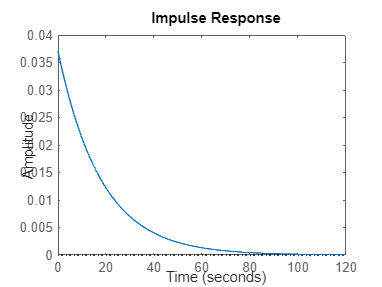


impulse(HTF)


roots(den)

ans = -0.0556

pole(HTF)

ans = -0.0556

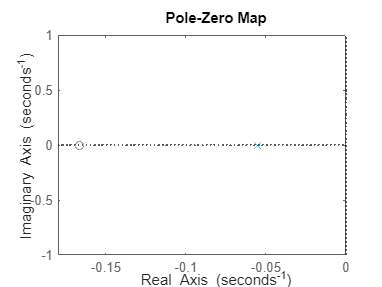

pzmap(HTF)

## Section 3 H = Vout/Vin

syms s R2 C2
Zc = 1/(s*C2)

$$Zc = \frac{1}{C_{2}\,s}$$

Zl = 1*s

$$Zl = s$$

Zs = simplifyFraction(R2+Zl)

$$Zs = R_{2}+s$$

H = simplifyFraction(Zc/(Zc+Zs))

$$H = \frac{1}{C_{2}\,s^{2}+C_{2}\,R_{2}\,s+1}$$

## Section 4

#### Section 4-1

R2 = 2; C2 = 1;
H = subs(H)

$$H = \frac{1}{s^{2}+2\,s+1}$$


[sysNum, sysDen] = numden(H)

$$sysNum = 1$$

$$sysDen = s^{2}+2\,s+1$$

num = sym2poly(sysNum)

num = 1

den = sym2poly(sysDen)

den =      1     2     1



HTF = tf(num,den)

HTF =
 
        1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


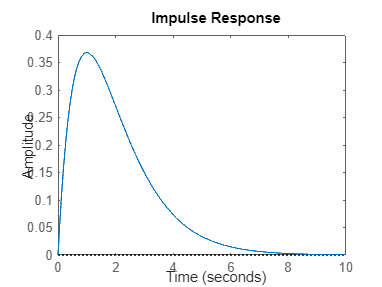


impulse(HTF)


pole(HTF)

ans =     -1
    -1


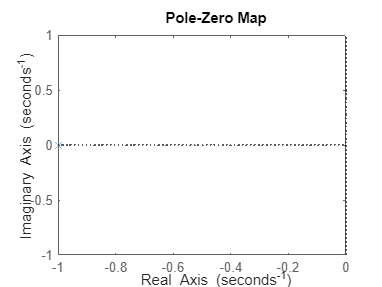

pzmap(HTF)

#### Section 4-2

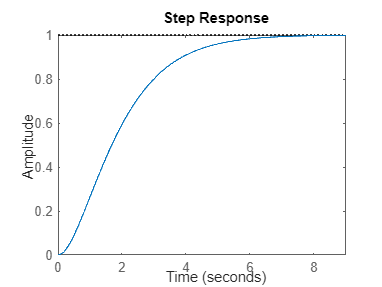

step(HTF)